## Reactive Obstacle Avoidance with State Machine

**18)** Test the behavior of the state machine for the input descreasing, increasing sequence $$r \in \{0.6 \rightarrow 0.1 \rightarrow 0.6\}$$. 

Since the `TurningBehavior` only possesses the single state `fullSpeed` the output $\omega$ is not affected. 

sfObject = sfAvoidObstacle('-warningOnUninitializedData', false); % instantiate stateflow object
statesTurn = {'TurningBehavior.goStraight', 'TurningBehavior.turnLeft', ...
              'TurningBehavior.turnRight', 'TurningBehavior.completeLeftTurn', ...
              'TurningBehavior.completeRightTurn'};
statesVelocity = {'VelocityBehavior.fullSpeed', 'VelocityBehavior.slowDown', ...
                  'VelocityBehavior.stop'};

r = [0.6:-0.025:0.1, 0.1:0.025:0.6];
phi = zeros(1,length(r));
phi(2:2:length(r)) = -0.2; % alternate phi
phi(1:2:length(r)) = 0.2;  % alternate phi

for i = 1:length(r)
    step(sfObject, 'r', r(i), 'phi', phi(i));
    v(i) = sfObject.v;
    omega(i) = sfObject.omega;
    stateSeriesTurn(i) = find(strcmp(statesTurn, sfObject.getActiveStates{2}));
    stateSeriesVelocity(i) = find(strcmp(statesVelocity, sfObject.getActiveStates{4}));
end

clear sfObject;

rsafe = 0.5;
rturn = 0.25;
rstop = 0.15;

subplot(311);
plot(1:length(r), r, 1:length(r), rsafe*ones(1,length(r)), '--', ...
     1:length(r), rturn*ones(1,length(r)), '--', ...
     1:length(r), rstop*ones(1,length(r)), '--', 'LineWidth', 2);
xlabel('steps');
ylabel('$r$', 'Interpreter', "latex");
legend({'$r$', '$r_{safe}$', '$r_{turn}$', '$r_{stop}$'}, 'Interpreter', "latex");

subplot(312);
plot(1:length(r), v, 1:length(r), omega, 'LineWidth', 2);
xlabel('steps');
ylabel('$v,\omega$', 'Interpreter', "latex");
legend({'$v$', '$\omega$'}, 'Interpreter', "latex");

subplot(313);
plot(1:length(r), stateSeriesTurn, 1:length(r), stateSeriesVelocity, 'LineWidth', 2);
xlabel('steps');
ylabel('$s$', 'Interpreter', "latex");
legend({'$s_\omega$', '$s_v$'}, 'Interpreter', "latex");

**19)** Augment the subchart of the `TurningBehavior` in the `sfAvoidObstacle.sfx` state machine by two states `turnLeft`, `turnRight` that correspond to the

	$r_{min}<r_{safe}$ and $\text{sgn}(\phi_{min})=\pm$. In both states calculate the turn rate $$\omega$$ according to the following Equations:


$$	|\omega| = \begin{cases}
	\omega_{max} & \text{for } \ \hat r_{min} < r_{turn} \\
	 \omega_{max} \frac{r_{safe}-\hat r_{min}}{r_{safe}-r_{turn}} &   \text{for } \  r_{turn} \leq \hat r_{min} \leq  r_{safe} \\
	0 & \text{for } \ \hat r_{min} > r_{safe} \end{cases}$$
 

and


$$\omega = - \text{sgn}(\phi_{min}) |\omega|$$


**20)** Add the conditions for the transitions between states:

- `goStraight` transits to either `turnLeft `or `turnRight` (depending on the sign of  $\phi$) once $$r<r_{safe}$$. 

- Vice versa, `turnLeft`, `turnRight` return to the state `goStraight` once $$r>r_{safe}$$.

- A transition between `turnLeft`, `turnRight` occurs whenever $\phi$ changes its sign.

**21)** Test the behavior of the augmented state machine for the the same sequence  $$r \in \{0.6 \rightarrow 0.1 \rightarrow 0.6\}$$ and an alternating sequence of $ $\phi = \pm 0.1$$. Observe the behavior of the turn rate $$\omega$$.

**22)** Augment the subchart of the `TurningBehavior` by two states `completeLeftTurn` and `completeRightTurn` that correspond to the case $$r_{min}<r_{turn}$$. The turn rate is constant $$\omega=\omega_{max}$$ for `completeLeftTurn` rsp. $$\omega=-\omega_{max}$$ for `completeLeftTurn`. 

**23)** Add the conditions for the transitions between states, `turnLeft`$$\leftrightarrow$$`completeLeftTurn` and `turnRight` $$\leftrightarrow$$ `completeRightTurn` depending on $$r<r_{turn}$$ or $$r>r_{turn}$$ . Notice, that the state machine has

	 no direct transition between `completeLeftTurn `and `completeRightTurn` to avoid an erratic behavior in corners.

**24)** Test the behavior of the augmented state machine for the the same sequence  $$r \in \{0.6 \rightarrow 0.1 \rightarrow 0.6\}$$ and

	an alternating sequence of $$\phi = \pm 0.1$$. Observe the behavior of the turn rate $\omega$ and the state sequence. If you implemented the state machine correctly you should observe the behavior shown in the figure below.

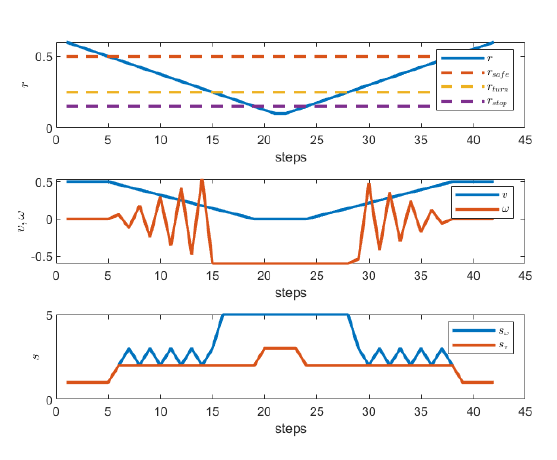

**25) ** Launch the turtlebot simulation and the navigation stack and set the initial pose estimate in rviz to the actual position displayed in Gazebo:

Reutilize your code (rated while loop and the scanCallback function) from the previous assignment (Robotics System Toolbox II - Scan Subscriber) here. Operate the state machine `sfAvoidObstacle` within the rated while loop of your program by passing the properties l`aserScan.rmin `and `laserScan.phimin` as name-value pairs (arguments `'r'` and `'phi'`) to the `step` function. Retrieve the translational velocity `SfObject.v` and turn rate `SfObject.omega` from the state machine object and compose a message of type `geometry_msg/Twist` with these values. Publish the message on the topic `/cmd_vel` to contol the robot. 

Test your obstacle avoidance in the Turtlebot simulation. Tune the parameters `rturn`, `rsafe`, `rstop` of the state machine such that the robots avoids collisions but traverses free areas at reasonable speed.

%% These comments indicate the coarse structure of the code. 
% You can copy and paste your code from the previous Scan Subscriber assignment here. 
% The additional steps for task 25) are marked in the comments below.


% rosshutdown and rosinit

% define the topic for laserscan results

% create a laserscanResult as class from scanhandle.m

% subscribe to scanTopic via Callback function
scanSub = rossubscriber(scanTopic,{@scanCallback,laserScan,beta,robotradius});

% define the topic for velocity commands

% create message and publisher for velocity topic

%% program loop
%define rate object for program loop in Hz and reset

% runtime in seconds
maxTime = 30;

% instantiate stateflow object

%define rate object for program loop in Hz and reset
rateObj = robotics.Rate(5);
rateObj.reset;

% program loop
while rateObj.TotalElapsedTime < maxTime
    % Draw arrow from sensors point of view
    
    % Task 25) call step function with sfObject. 
     
    % Task 25) Write v and omega to velocity message
    
    % Task 25) Send message to rst_turtle_bot
    
    % Wait for next loop cycle to be executed at rateObj.Rate (5 Hz)
    waitfor(rateObj);
end

%% finish
% set all movements to 0

% Send message to stop turtlebot

% clear sfObject

% clear subscribers

**26)** Test the ability of your obstacle avoidance behavior and state machine to navigate the robot out of corners. 

#### **Helper Functions**

function scanCallback(~,scanMsg,laserscan, varargin)
    % Copy your scanCallback function here
end